## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Vectors**

## **Lab Session 1**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)**** definida no ficheiro chirpTone.m****.*

**b) **Listen the sound with f1 = 100, f2 = 2000 and fs = 4000 Hz.

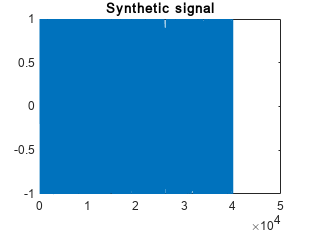

sData = chirpTone(10,100,2000,4000); %synthetic data

soundsc(sData); %listen to it

**c) **Save the sound vector in an audio file to be read in normal audio players

fs = 4000; %sampling rate
audiowrite('synthetic.wav',sData,fs); %save in an audio file

# **2) Real data**

**a) Audio (1D)**

**i) **Read the audio file ”Let It Be.mp3”.

rData = audioread("Let It Be.mp3"); %real data

**b) **Compute the length of the file in seconds. Explain the approach you used. 

%informação acerca do ficheiro de áudio
audioinfo("Let It Be.mp3");
%retirar a sample rate
SRate = audioinfo("Let It Be.mp3").SampleRate;
%determinar o número de samples
SNumber = size(rData,1); % SNumber = audioinfo("Let It Be.mp3").TotalSamples
%a duração do ficheiro é igual ao número de samples sobre a sample rate
SLength = SNumber/SRate;

**c) **Reproduce the music backwards.

bData = flipud(rData); %flipped
%soundsc(bData);
soundsc(rData)

**b) Electrocardiogram (1D)**

**i) **Read the *.mat file ”116m(2).mat” containing a real ECG trace. 

**ii) **Visualize the ECG trace and comment. 

**iii)** Estimate the sampling frequency that leads to a realistic ECG trace. 

**iv) **Detect the R peaks and estimate the heart rate (HR) from the inter-peak intervals. 